# Linear Control Design II - Group Work Problem Module 9

## Description		

The airplane model is to be extended by adding a second input: The aileron angle $\delta_a$ as shown on figure 1. The roll angle$\varphi$ is also added to the output vector. 

  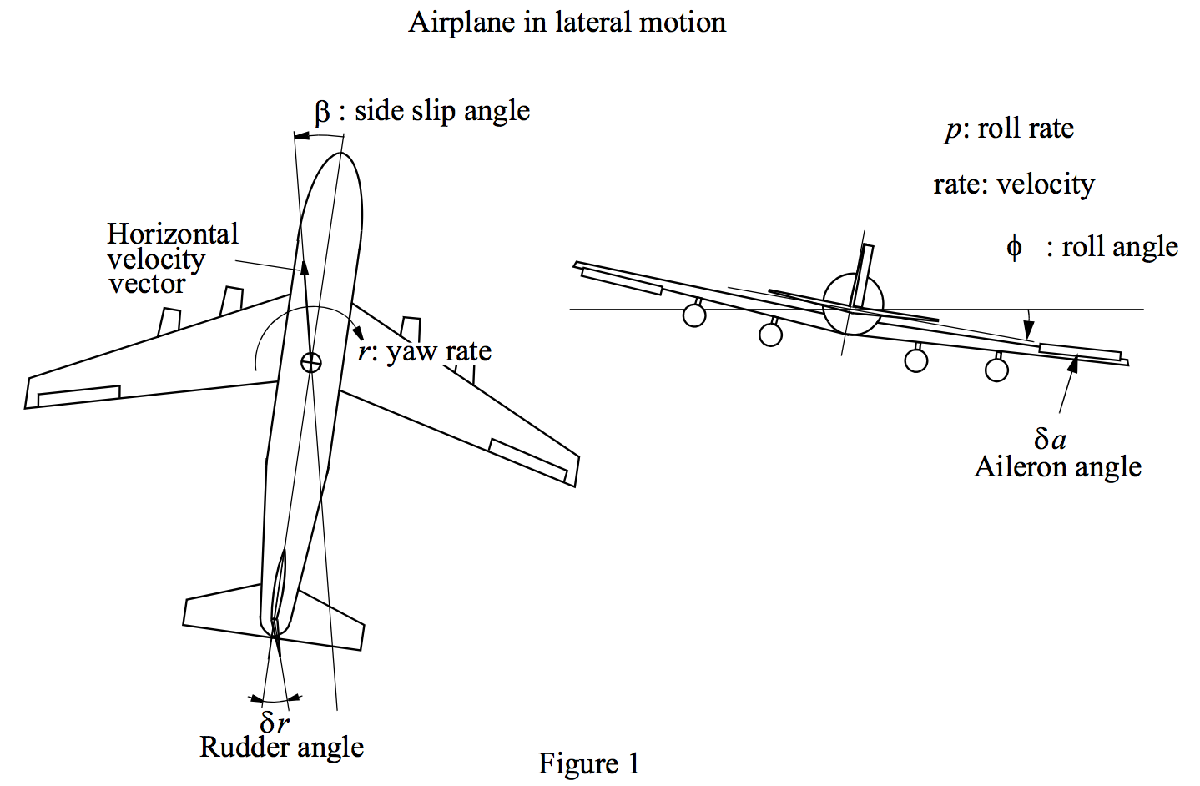

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:


$$\pmatrix{ \dot{\beta} \cr \dot{r} \cr \dot{p} \cr \dot{\varphi} } = \pmatrix{ -0.0558 &\ -0.9968 &\ 0.0802 &\ 0.0415 \cr 0.5980 &\ -0.1150 &\ -0.0318 &\ 0 \cr -3.0500 &\ 0.3880 &\ -0.4650 &\ 0 \cr 0 &\ 0.0805 &\ 1 &\ 0 } \pmatrix{ \beta \cr r \cr p \cr \varphi } + \pmatrix{ 0.00729 &\ 10^{-5} \cr -0.47500 &\ 0.123\cr 0.15300 &\ 1.063\cr 0 &\ 0} \pmatrix{ \delta r \cr \delta a }$$

$$y = \pmatrix{ 0 \ 1 \ 0 \ 0 \cr 0 \ 0 \ 0 \ 1 } \pmatrix{ \beta \cr r \cr p \cr \varphi}$$


where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), $\delta_r$ is the rudder deflection (rad) and $\delta_a$ is the aileron angle (rad).

format short g; clear all; close all; clc;

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

% Define state-space system:
sys_ss = ss(A,B,C,D)


sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729    1e-05
   x2   -0.475    0.123
   x3    0.153    1.063
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Problem 1  **Is the system controllable and observable?

*Use the controllability and observability matrices *$\mathbf{M_c}$* and *$\mathbf{M_o}$* (Matlab functions ctrb and obsv). How would you test whether *$\mathbf{M_c}$* has 4 linearly independent columns?*

*Also use the test with the left and the right eigenvectors (first part of PBH-test, i.e. the criteria CC3 and OC3) and the diagonal test (CC4 and OC4).*

**Solution****:**

% Your solution goes here:




**Problem 2  **Find the 4 transfer functions and determine the 4 sets of poles and zeros. 

**Solution:**

% Your solution goes here:




**Problem 3  **Set up a detailed Simulink model of the airplane. Base the model on figure 2.3 in the textbook. Note: One can use the MatrixGain-block as well as the usual Gain-block, but be sure that it is set up for matrix-multiplication. 

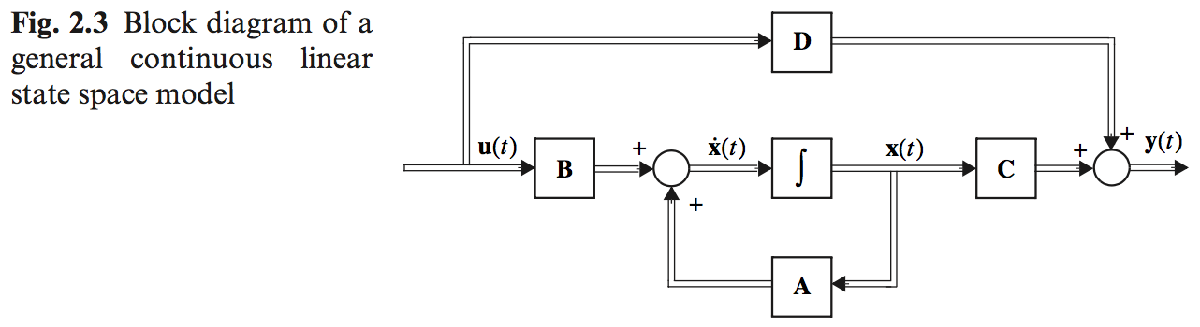

**Solution:**

% Your solution goes here:




**Problem 4  **Find the 4 step responses (use the angle 1° for both inputs) and plot them in a 2 by 2 array using Matlab’s subplot-function. 

**Solution:**

% Your solution goes here:




**Problem 5**  Last, simulate the response of the linear system by using the function on figure 2 at both inputs, but one at a time.

Is it possible to change the airplane’s heading by manipulating the ailerons only? 

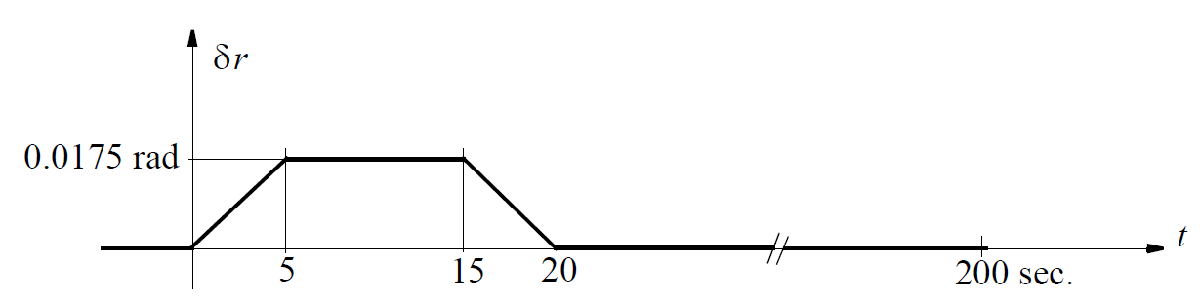	

**Solution:**

% Your solution goes here:


